## **Die logistische Funktion**

Die logistische Funktion ist definiert als $\sigma(z) = \frac{1}{1+e^{-z}}$.

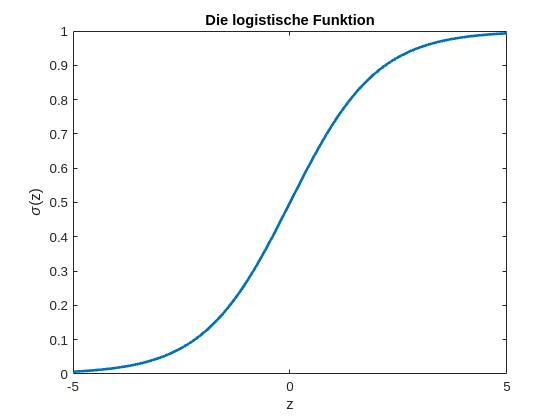

sigmoid = @(z) 1./(1+exp(-z));
z = linspace(-5,5);
plot(z, sigmoid(z));   
title('Die logistische Funktion')
xlabel('z'), ylabel('\sigma(z)')

In den Anwendungen taucht die Funktion oft in der Form $\sigma(wz+b)$mit dem Gewicht $w$ und dem Bias $b$ auf. 

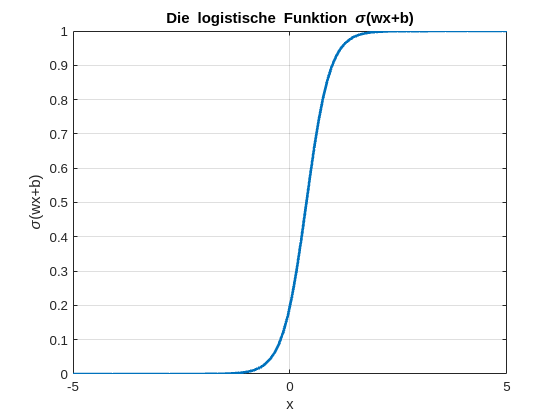

b =-1.4;
w = 3.7; 
x = linspace(-5,5);
z = w*x + b; 
plot(x, sigmoid(z));   
title('Die logistische Funktion \sigma(wx+b)');
xlabel('x'), ylabel('\sigma(wx+b)');
grid on; 

## Die Softmax-Funktion

Die Softmax-Funktion bildet einen Vektor mit $C$ Komponenten wiederrum auf einen Vektor mit $C$ Komponenten und ist definiert als $s\left(z_1 ,\ldotp \ldotp \ldotp ,z_C \right)=\frac{\left(e^{z_1 \;\;} ,\ldotp \ldotp \ldotp ,e^{z_C } \right)}{e^{z_1 \;\;} +\;\ldotp \ldotp \ldotp +\;e^{z_C } }$

Naive Implementierung: 

smNaive = @(zVec) exp(zVec) ./ sum(exp(zVec));
zv1 = [0.8, 0.9, 0.1]; 
disp(smNaive(zv1));

      0.38436      0.42478      0.19087



disp(smNaive(10*zv1));

      0.26888      0.73088   0.00024518



disp(smNaive(100*zv1));

   4.5398e-05      0.99995   1.8048e-35



disp(smNaive(1000*zv1));

   NaN   NaN     0



Vergleich mit einer der stabileren Implementierung

disp([smNaive(zv1); sm(zv1)]);

      0.38436      0.42478      0.19087
      0.38436      0.42478      0.19087



disp([smNaive(10*zv1);sm(10*zv1)]);

      0.26888      0.73088   0.00024518
      0.26888      0.73088   0.00024518



disp([smNaive(100*zv1); sm(100*zv1)]);

   4.5398e-05      0.99995   1.8048e-35
   4.5398e-05      0.99995   1.8048e-35



disp([smNaive(1000*zv1); sm(1000*zv1)]);

          NaN          NaN            0
   3.7201e-44            1            0



Warum heißt die Funktion softmax? Weil sie für große Argumente die Komponente mit dem größten Wert rauspickt. 

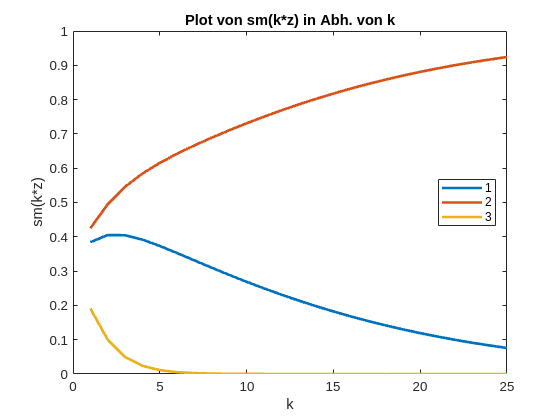

zv1 = [0.8, 0.9, 0.1]; 
kVec = 1:25; 
smMat = zeros(length(zv1), length(kVec));
for kk=1:length(kVec)
    smMat(:,kk) = sm(kVec(kk)*zv1);
end
plot(kVec, smMat');
title('Plot von sm(k*z) in Abh. von k');
xlabel('k'), ylabel('sm(k*z)');
legend('1', '2', '3', 'Location', 'East');

## Vergleich Softmax mit 2 Variablen und logistische Funktion

Für $C=2$ hängen Softmax und logistische Funktion eng miteinander zusammen, nämlich $s\left(z,0\right)=\left(\sigma \left(z\right),1-\sigma \left(z\right)\right)$

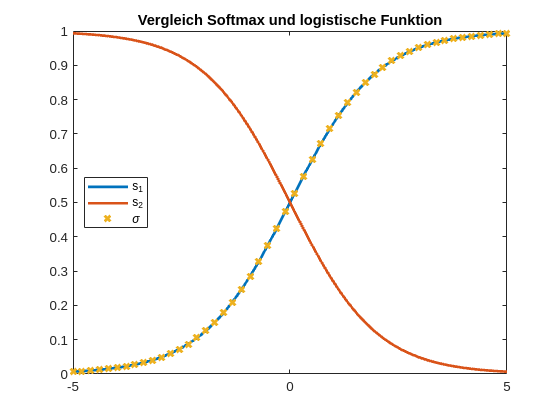

z = linspace(-5,5, 50);
smWerte = cell2mat(arrayfun(@(zz) sm([zz, 0])', z, 'UniformOutput',false));
plot(z, smWerte(1,:), z, smWerte(2,:), z, sigmoid(z), 'x'); 
legend('s_1', 's_2', '\sigma', 'Location', 'West');
title('Vergleich Softmax und logistische Funktion')